clear


# Tavlenoter

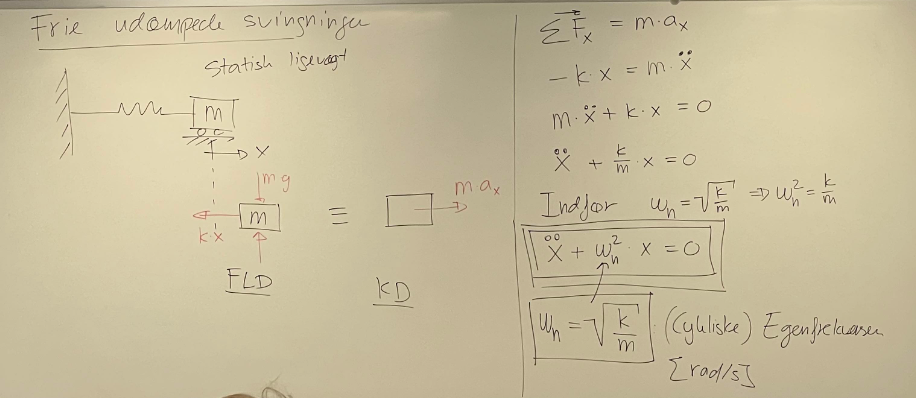

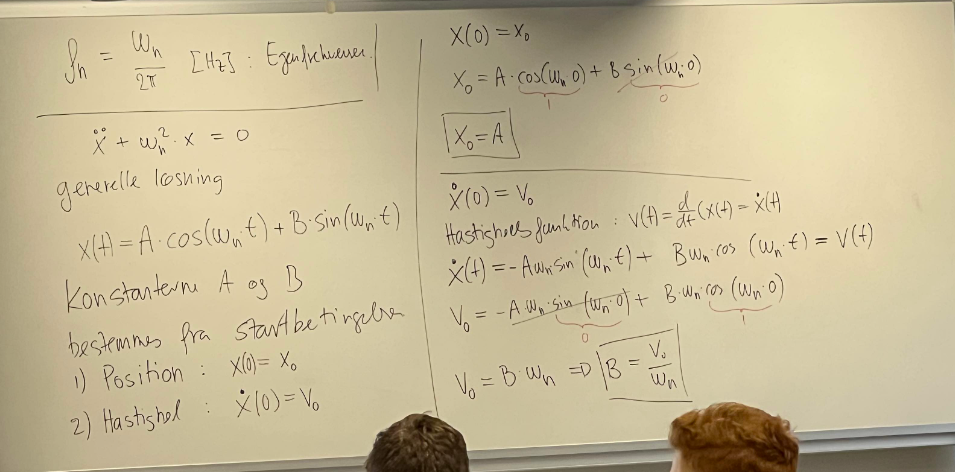

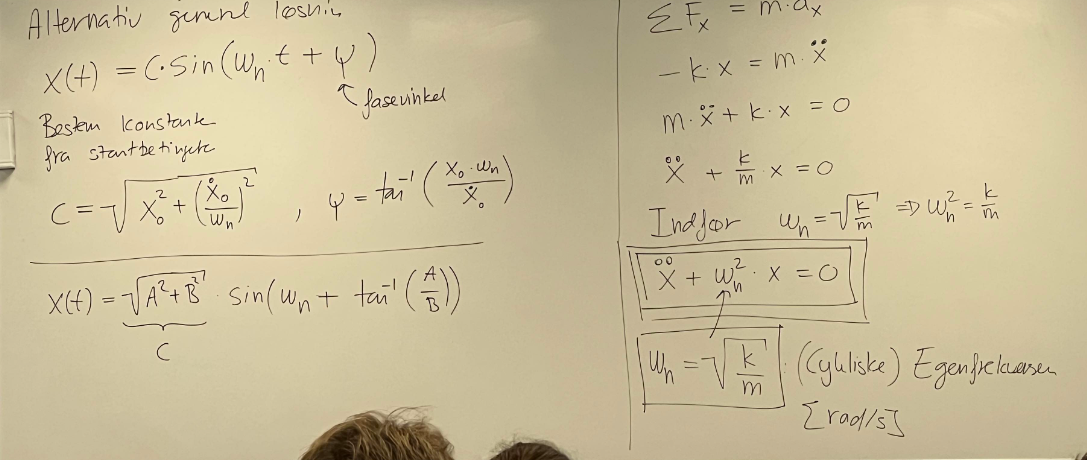

# Opgave 8.4

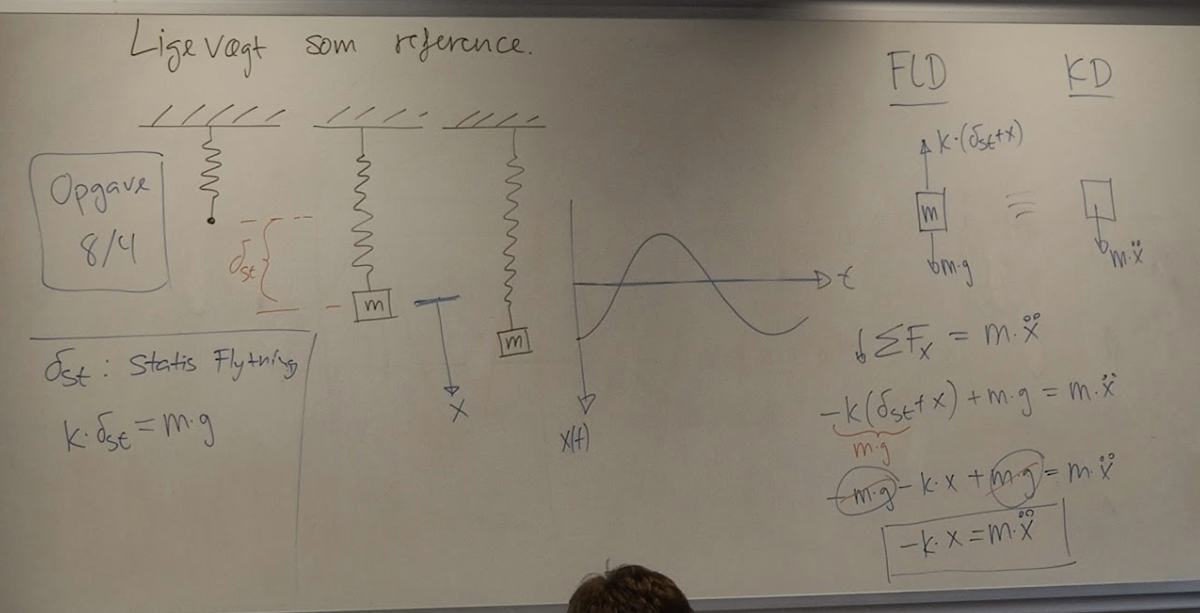

# Første lektion

% Første lektion misset
% Opgaver fra Martin - tjek hans git


# Anden lektion

clear

syms zeta lambda t A wn k m



eq = A*lambda^2*exp(lambda*t) + 2*zeta*A*wn*lambda*exp(lambda*t) + wn^2*A*exp(lambda*t) == 0

$$eq = A\,\lambda^{2}\,{\mathrm{e}}^{\lambda \,t}+A\,{\mathrm{wn}}^{2}\,{\mathrm{e}}^{\lambda \,t}+2\,A\,\lambda \,\mathrm{wn}\,\zeta \,{\mathrm{e}}^{\lambda \,t}=0$$




sol = solve(eq, lambda)

$$sol = \left(\begin{array}{c} \mathrm{wn}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\mathrm{wn}\,\zeta \\ -\mathrm{wn}\,\sqrt{\left(\zeta -1\right)\,\left(\zeta +1\right)}-\mathrm{wn}\,\zeta \end{array}\right)$$

simplify(sol)

$$ans = \left(\begin{array}{c} -\mathrm{wn}\,\left(\zeta -\sqrt{\zeta^{2}-1}\right)\\ -\mathrm{wn}\,\left(\zeta +\sqrt{\zeta^{2}-1}\right) \end{array}\right)$$



%%%%



clear
syms x(t) zeta lambda t A wn k m

eq = lambda^2 + 2*zeta*wn*lambda + wn^2 == 0

$$eq = \lambda^{2}+2\,\zeta \,\lambda \,\mathrm{wn}+{\mathrm{wn}}^{2}=0$$


sols = solve(eq, lambda);
simplify(sols)

$$ans = \left(\begin{array}{c} -\mathrm{wn}\,\left(\zeta -\sqrt{\zeta^{2}-1}\right)\\ -\mathrm{wn}\,\left(\zeta +\sqrt{\zeta^{2}-1}\right) \end{array}\right)$$

clear
syms x(t) zeta lambda t A wn k m C wd


% Generel løsning



assume(zeta == 1)
deq = diff(x,t,2) + 2*zeta*wn*diff(x,t) + wn^2*x(t);

dsol = dsolve(deq);
simplify(dsol)

$$ans = {\mathrm{e}}^{-t\,\mathrm{wn}}\,\left(C_{1}+C_{2}\right)$$


% Zeta conditions

wn = sqrt(k/m);
zeta = C/(2*m*wn);

% Zeta = 1
assume(zeta == 1)

dsol2 = dsolve(deq);

simplify(dsol2)

$$ans = {\mathrm{e}}^{-t\,\mathrm{wn}}\,\left(C_{1}+C_{2}\right)$$



% Zeta < 1

assume(zeta < 1)

dsol3 = dsolve(deq);

simplify(dsol3)

$$ans = {\mathrm{e}}^{-t\,\mathrm{wn}}\,\left(C_{1}+C_{2}\right)$$


% Zeta > 1

assume(zeta > 1)

dsol4 = dsolve(deq);

simplify(dsol4)

$$ans = {\mathrm{e}}^{-t\,\mathrm{wn}}\,\left(C_{1}+C_{2}\right)$$

clear all

% Data fra opgaven
m = 8;  x0 = 0.2;   t0 = 0; t1 = 2; Cd = 20; k = 32;

% Formler

wn1 = sqrt(k/m)

wn1 =      2


zeta1 = Cd/(2*m*wn1)

zeta1 =         0.625


wd1 = wn1*sqrt(1 - zeta1^2)

wd1 =        1.5612



% Diff ligning
syms x(t) zeta lambda t A wn k m C wd psi x

x_plac = C*exp(-zeta*wn*t) * sin(wd*t + psi) == x0;
% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3)

$$x\_plac\_numt0 = C\,\sin\left(\psi \right)=0.2$$

% til t1
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3)

$$x\_plac\_numt1 = 0.0821\,C\,\sin\left(\psi +3.12\right)=0.2$$


x_vel = diff(x_plac, t) == 0

$$x\_vel = \left(C\,\mathrm{wd}\,{\mathrm{e}}^{-t\,\mathrm{wn}\,\zeta }\,\cos\left(\psi +t\,\mathrm{wd}\right)-C\,\mathrm{wn}\,\zeta \,{\mathrm{e}}^{-t\,\mathrm{wn}\,\zeta }\,\sin\left(\psi +t\,\mathrm{wd}\right)=0\right)=0$$

% til t0
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3)

$$x\_vel\_numt0 = \left(1.56\,C\,\cos\left(\psi \right)-1.25\,C\,\sin\left(\psi \right)=0.0\right)=0.0$$

% til t1
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3)

$$x\_vel\_numt1 = \left(0.128\,C\,\cos\left(\psi +3.12\right)-0.103\,C\,\sin\left(\psi +3.12\right)=0.0\right)=0.0$$



eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, psi];

solt0 = solve(eqst0, unks)

solt0 = struct with fields:
      C: [2×1 sym]
    psi: [2×1 sym]


solt1 = solve(eqst1, unks)

solt1 = struct with fields:
      C: [2×1 sym]
    psi: [2×1 sym]



solt0.C(1)

$$ans = -0.2562050460898422883677763457003$$

solt0.psi(1)

$$ans = -2.2459278597356859469901745164926$$

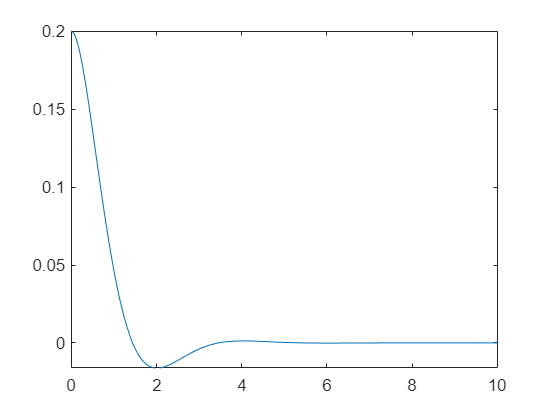

syms func(t)
func(t) = solt0.C(1)*exp(-zeta1*wn1*t) * sin(wd1*t + solt0.psi(1));

fplot(func(t), [0,10])

clear
% Data fra opgaven
m = 50;  x0 = 0.15;   t0 = 0; t1 = 0.5; Cd = 200; k = 200;

% Formler

wn1 = sqrt(k/m)

wn1 =      2


zeta1 = Cd/(2*m*wn1)

zeta1 =      1


wd1 = wn1*sqrt(1 - zeta1^2)

wd1 =      0



syms A1 A2 t x1

x_plac_t0 = (A1 + A2*t)*exp(-wn1*t) == x0

$$x\_plac\_t0 = {\mathrm{e}}^{-2\,t}\,\left(A_{1}+A_{2}\,t\right)=\frac{3}{20}$$

x_plac_t1 = (A1 + A2*t)*exp(-wn1*t) == x1

$$x\_plac\_t1 = {\mathrm{e}}^{-2\,t}\,\left(A_{1}+A_{2}\,t\right)=x_{1}$$

x_vel = diff(x_plac_t0, t)

$$x\_vel = A_{2}\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-2\,t}\,\left(A_{1}+A_{2}\,t\right)=0$$



eq1 = x_plac_t0 == x0;
eq2 = x_vel == x1

$$eq2 = \left(A_{2}\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-2\,t}\,\left(A_{1}+A_{2}\,t\right)=0\right)=x_{1}$$


eqs = [eq1, eq2];
vars = [A1, A2];

sols = solve(eqs, vars);
sols.A1

$$ans = -\frac{3\,{\mathrm{e}}^{2\,t}\,\left(2\,t-1\right)}{20}$$

A1_ny = subs(sols.A1, t, t0)

$$A1\_ny = \frac{3}{20}$$

A2_ny = subs(sols.A2, t, t0)

$$A2\_ny = \frac{3}{10}$$


svar = subs(x_plac_t1, [A1, A2, t], [A1_ny, A2_ny, t1]);
vpa(svar, 4)

$$ans = 0.1104=x_{1}$$

clear all
format short
% Data fra opgaven
m = 50;  x0 = 0.15;   t0 = 0; t1 = 0.5; Cd = 300; k = 200;

% Formler

wn = sqrt(k/m)

wn = 2

zeta = Cd/(2*m*wn)

zeta = 1.5000

wd = wn*sqrt(1 - zeta^2)

wd = 0.0000 + 2.2361i


% Diff ligninger (skal rettes lidt til) - plus conditions

syms A1 A2 t x1

x_plac_t0 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x0;
x_plac_t1 = A1*exp((-zeta + sqrt(zeta^2 - 1))*wn*t) + A2*exp((-zeta-sqrt(zeta^2-1))*wn*t) == x1;

x_vel = diff(x_plac_t0, t);


eq1 = x_plac_t0 == x0;
eq2 = x_vel == x1;

eqs = [eq1, eq2];
vars = [A1, A2];

% Konstanterne A1 og A2 udregnes, og sættes ind i diff ligningerne sammen
% med t1

sols = solve(eqs, vars);

A1_ny = vpa(subs(sols.A1, t, t0),3)

$$A1\_ny = 0.176$$

A2_ny = vpa(subs(sols.A2, t, t0),3)

$$A2\_ny = -0.0256$$


svar = subs(x_plac_t1, [A1, A2, t], [A1_ny, A2_ny, t1]);
vpa(svar, 4)

$$ans = 0.118=x_{1}$$

function vibra = displacement(t0, t1, x0, k, m, Cd)

wn1 = sqrt(k/m);
zeta1 = Cd/(2*m*wn1)
wd1 = wn1*sqrt(1 - zeta1^2);

% Diff ligning
syms x(t) zeta lambda t A wn k m C wd ps

% If statement over de forskellige scenarier

if zeta1 < 1
    syms C zeta wn t wd ps 
    x_plac = C*exp(-zeta*wn*t) * sin(wd*t + ps) == x0
elseif zeta1 == 1
    syms A1 A2 t wn x0
    x_plac = (A1 + A2*t)*exp(-wn*t) == x0;
elseif zeta1 > 1
    syms A1 A2 zeta wn t  x0
    x_plac = A1*exp(-zeta + sqrt(zeta^2 - 1)*wn*t + A2*exp(-zeta-sqrt(zeta^2-1)*wn*t)) == x0;
end

% Til t0
x_plac_numt0 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t0]),3)
% til t1
x_plac_numt1 = vpa(subs(x_plac, [zeta, wn, wd, t], [zeta1, wn1, wd1, t1]),3)

x_vel = diff(x_plac, t) == 0
% til t0
x_vel_numt0 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t0]),3)
% til t1
x_vel_numt1 = vpa(subs(x_vel, [wd, wn, zeta, t], [wd1, wn1, zeta1, t1]),3)


eqst0 = [x_vel_numt0, x_plac_numt0];
eqst1 = [x_vel_numt1, x_plac_numt1];
unks = [C, ps];

solt0 = solve(eqst0, unks)
solt1 = solve(eqst1, unks);

Ct_0 = solt0.C(1)
psi_0 = solt0.ps(1)


syms func(t)
func(t) = Ct_0(1)*exp(-zeta1*wn1*t) * sin(wd1*t + psi_0(1));

fplot(func(t), [0,10])
end
